 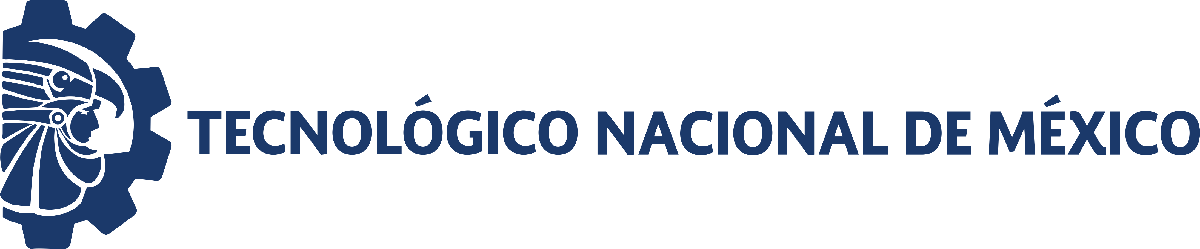                                 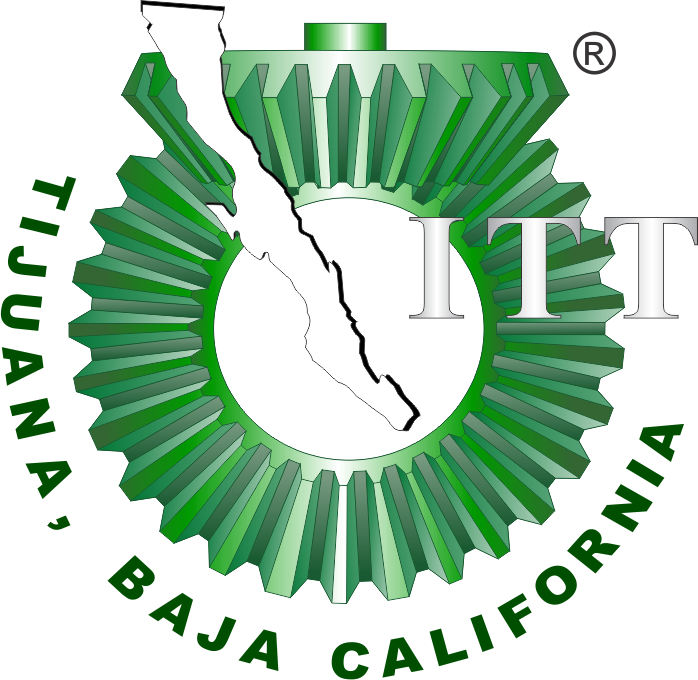

# Proyecto Final

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

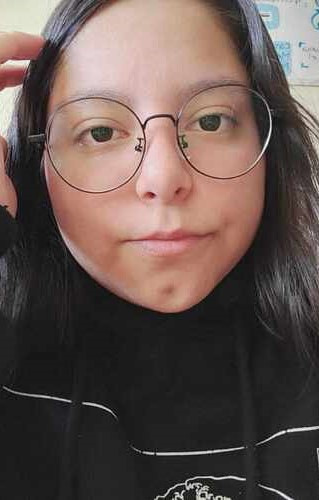

Nombre del alumno: **Diana Ivana Escalante Esquivel**

Número de control: **21212151**

Correo institucional: **L21212151@tectijuana.edu.mx**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Objective

Integrar las competencias específicas relacionadas con el modelizado, análisis y control de sistemas biológicos para ilustrar y predecir su dinámica a lo largo del tiempo.

## System description

El sistema representa la dinámica de la inflamación aguda en un tejido humano, modelando la interacción entre tres poblaciones celulares y moleculares clave:

1. $x$: Células dañadas por inflamación. Representan células del tejido que han sido alteradas o destruidas por un estímulo inicial, como una herida, infección o exposición a toxinas.

2. $y$: Macófagos. Son células inmunes que se reclutan al sitio del daño. Se encargan de fagocitar células dañadas, liberar mediadores inflamatorios y regular el inicio y la resolución de la inflamación.

3. $z$: Citoquinas inflamatorias. Son proteínas mensajeras secretadas por las células dañadas y por los macrófagos. Su función es amplificar la respuesta inmune, promoviendo la activación de más macrófagos.

Las ecuaciones que describen las interacciones entre las tres poblaciones involucradas en el proceso inflamatorio se presentan a continuación:

1. $\dot{x} =\rho_1 \mathrm{xz}-\rho_2 x$

2. $\dot{y} =\rho_3 \mathrm{xyz}-\rho_4 y$

3. $\dot{z} =\rho_5 z-p_6 \mathrm{xz}$

 Explicación de las ecuaciones del modelo:

1. Las citoquinas inflamatorias estimulan la respuesta inflamatoria del organismo, promoviendo el reclutamiento de células inmunes mediante el aumento del flujo sanguíneo y la permeabilidad vascular. Sin embargo, una producción excesiva de citoquinas puede amplificar el daño tisular (inflamación descontrolada). Por otro lado, los macrófagos activados intervienen para eliminar las células dañadas.

2. Los macrófagos son activados y reclutados al sitio de la lesión en respuesta a señales provenientes tanto de las células dañadas como de las citoquinas inflamatorias. Una vez activados, participan en la eliminación del tejido dañado y la producción de nuevas citoquinas. No obstante, tras la resolución del daño, los macrófagos pueden sufrir apoptosis (muerte celular programada) o retirarse del sitio, lo que reduce su población activa.

3. Las citoquinas inflamatorias continúan produciéndose mientras persistan señales de daño tisular, siendo su síntesis estimulada principalmente por la presencia de células dañadas y macrófagos activados. Sin embargo, a medida que el tejido comienza a recuperarse y el estímulo inflamatorio disminuye, estas citoquinas pueden ser degradadas o neutralizadas. Paralelamente, se inicia la secreción de citoquinas antiinflamatorias, las cuales se unen a receptores en células inmunes, modulando su actividad y suprimiendo la producción de citoquinas proinflamatorias, favoreciendo así la resolución del proceso inflamatorio.

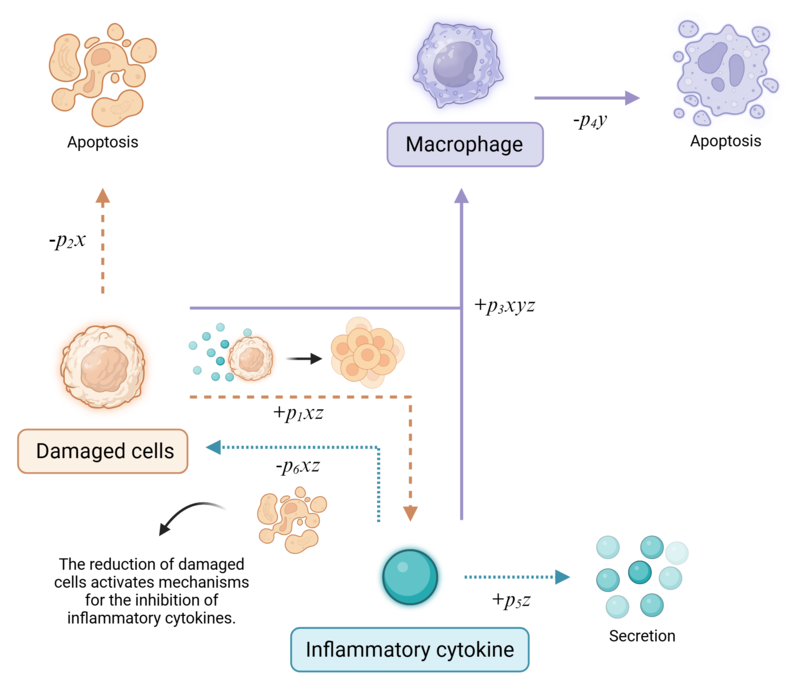

*Figure 1. Predator-prey system model of the inflammation process.*

## Simulation data

    to     xo       yo       zo  
    __    _____    _____    _____

     0    6.423     1.72    6.319
     7    6.752    2.224    6.228
    14    7.414    2.873    6.043
    21    7.852    3.467    5.832
    28     8.15    4.126    5.682
    35    8.548    4.815    5.456
    42    8.997    5.615     5.13
    49     8.94    6.476    4.892
    56    8.581    7.091    4.615
    63    8.099    7.457    4.188
    70    7.661    7.715    3.911



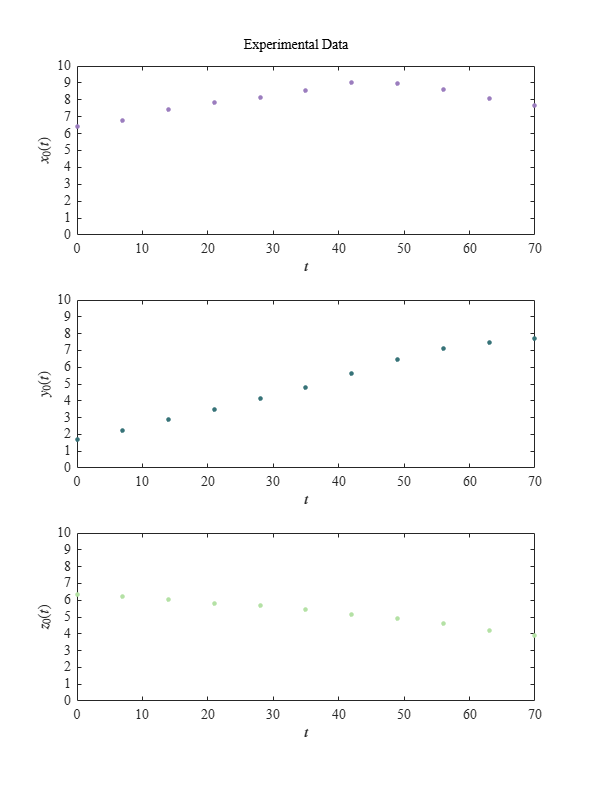

clc; clear; close all; warning('off','all')
sys = readmatrix('data.csv');
to = sys(:,1);
xo = sys(:,2);
yo = sys(:,3);
zo = sys(:,4);
T = array2table([to,xo,yo,zo],'VariableNames',{'to','xo','yo','zo'});
disp(T); plotdata(to,xo,yo,zo);

## Smooth data

    to      xo        yo        zo  
    __    ______    ______    ______

     0    6.5875    2.2723    6.1967
     7     6.863     2.571    6.1055
    14    7.1102     2.882    6.0208
    21     7.542     3.501    5.8482
    28     7.991    4.1792    5.6286
    35    8.3867    4.8998    5.3984
    42    8.6587    5.6246     5.155
    49    8.7665    6.2908    4.8562
    56    8.6542    6.8708    4.5472
    63    8.3202    7.1848    4.4015
    70    8.1137     7.421     4.238



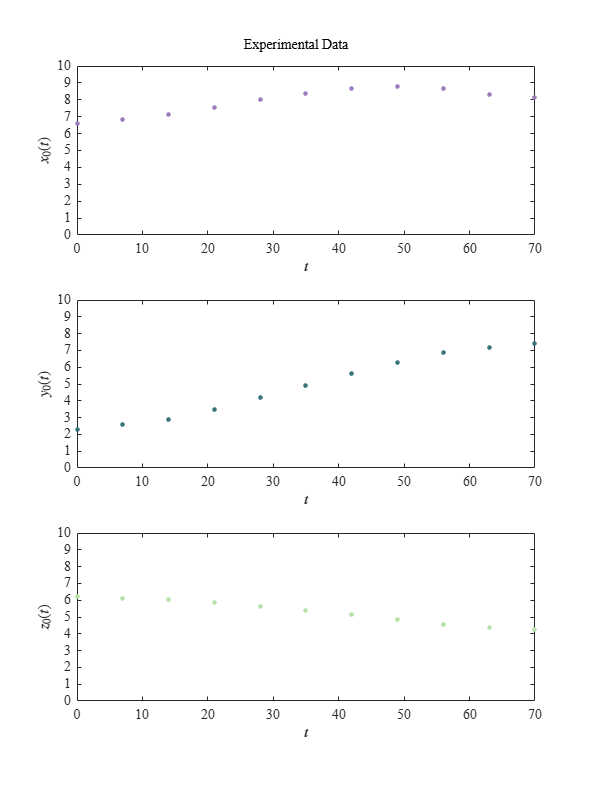

xo = smoothdata(xo);
yo = smoothdata(yo);
zo = smoothdata(zo);
T = array2table([to,xo,yo,zo],'VariableNames',{'to','xo','yo','zo'});
writetable(T, 'smooth_data.csv');
disp(T); plotdata(to,xo,yo,zo);

## Normalized data

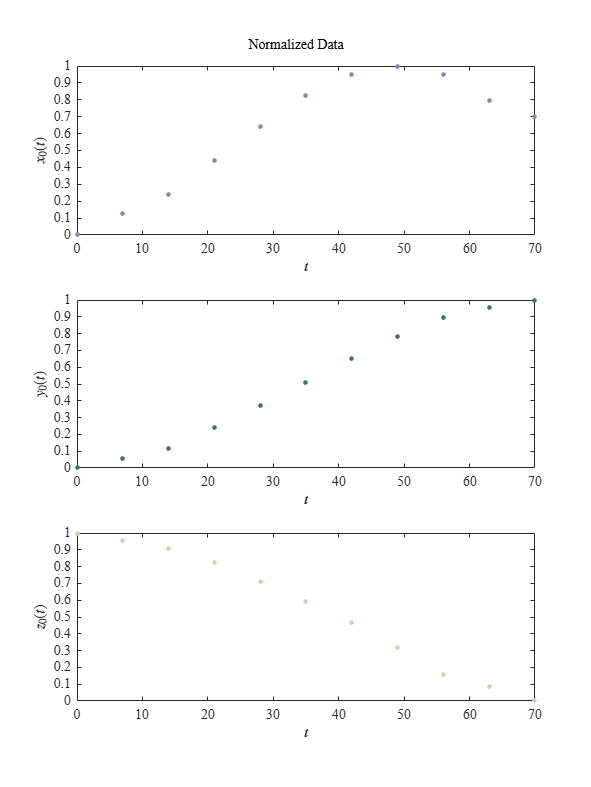

xo_norm = (xo - min(xo)) / (max(xo) - min(xo));
yo_norm = (yo - min(yo)) / (max(yo) - min(yo));
zo_norm = (zo - min(zo)) / (max(zo) - min(zo));
plotNormalizedData(to,xo_norm,yo_norm,zo_norm);

## Fit data


Sample size (n): 11
Parameters to be estimated (pars): 6
Degrees of freedom: 27
Significance level (alpha): 0.05
t-Student value: 2.0518
R-squared: 0.99719
Corrected AIC (n/pars < 40): -46.1972

    Parameters    Estimate         SE           MoE                 CI95               pvalue  
    __________    _________    __________    __________    ______________________    __________

       rho1       0.0060969    0.00045191    0.00092725    0.0051697    0.0070242    1.6255e-13
       rho2        0.029364     0.0025075      0.005145     0.024219     0.034509    4.3303e-12
       rho3        0.002147    0.00023565    0.00048352    0.0016635    0.0026305    1.0061e-09
       rho4        0.074031      0.010099      0.020721      0.05331     0.094753    6.9388e-08
       rho5        0.02

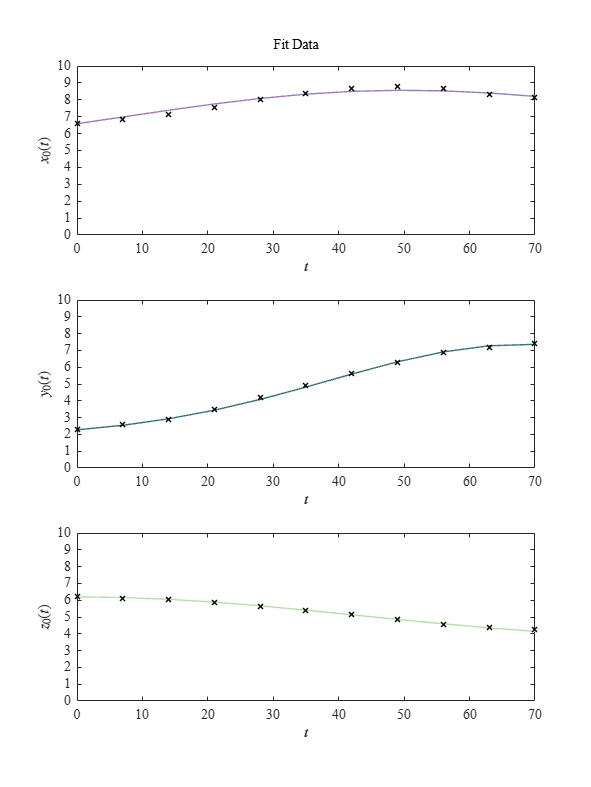

rho1 = 0.00705; rho2 = 0.0351;
rho3 = 0.00198; rho4 = 0.0667;
% rho3 = 0.00996; rho4 = 0.0355;
% rho3 = 0.000198; rho4 = 0.0267;
rho5 = 0.0187; rho6 = 0.00306;
P = [rho1, rho2, rho3, rho4, rho5, rho6];
[mdl, xa, ya, za] = variant(to,xo,yo,zo,P); plotResults(to, [xo,xa], [yo,ya], [zo,za]);

## Equilibrium points and Jacobian matrix

syms x y z rho1 rho2 rho3 rho4 rho5 rho6
dx = rho1*x*z - rho2*x;
dy = rho3*x*y*z - rho4*y

$$dy = \rho_{3}\,x\,y\,z-\rho_{4}\,y$$

dz = rho5*z - rho6*x*z;
J = jacobian([dx,dy,dz],[x,y,z]);
fprintf('Jacobian matrix:'); disp(J);

Jacobian matrix:

$$\left(\begin{array}{ccc} \rho_{1}\,z-\rho_{2} & 0 & \rho_{1}\,x\\ \rho_{3}\,y\,z & \rho_{3}\,x\,z-\rho_{4} & \rho_{3}\,x\,y\\ -\rho_{6}\,z & 0 & \rho_{5}-\rho_{6}\,x \end{array}\right)$$

dx = rho1*x*z - rho2*x == 0;
dy = rho3*x*y*z - rho4*y == 0;
dz = rho5*z - rho6*x*z == 0;
edos = solve([dx,dy,dz],[x,y,z]);
fprintf(['The system has ', num2str(length(edos.x)), ' equilibrium points.']);

The system has 2 equilibrium points.

X0 = edos.x(1); Y0 = edos.y(1); Z0 = edos.z(1);
X1 = edos.x(2); Y1 = edos.y(2); Z1 = edos.z(2);
syms x0 y0 z0 x1 y1 z1
fprintf('Equilibrium points of the system:\n'); disp([x0, y0, z0, X0, Y0, Z0]); disp([x1, y1, z1, X1, Y1, Z1]);

Equilibrium points of the system:


$$\left(\begin{array}{cccccc} x_{0} & y_{0} & z_{0} & 0 & 0 & 0 \end{array}\right)$$

$$\left(\begin{array}{cccccc} x_{1} & y_{1} & z_{1} & \frac{\rho_{5}}{\rho_{6}} & 0 & \frac{\rho_{2}}{\rho_{1}} \end{array}\right)$$

clear rho1 rho2 rho5 rho6
rho1 = 0.00705; rho2 = 0.0351;
rho5 = 0.0187; rho6 = 0.00306;
disp('(x0, y0, z0) = (0, 0, 0)'); disp(['(x1,y1,z1) = (', num2str(rho5/rho6), ', ', num2str(0), ', ', num2str(rho2/rho1), ')']);

(x0, y0, z0) = (0, 0, 0)
(x1,y1,z1) = (6.1111, 0, 4.9787)


## Local stability

clear rho1 rho2 rho3 rho4 rho5 rho6
rho1 = 0.00705; rho2 = 0.0351;
rho3 = 0.00198; rho4 = 0.0667;
rho5 = 0.0187; rho6 = 0.00306;
dx = rho1*x*z - rho2*x == 0;
dy = rho3*x*y*z - rho4*y == 0;
dz = rho5*z - rho6*x*z == 0;
edos = solve([dx,dy,dz],[x,y,z]);
x0 = edos.x(1); y0 = edos.y(1); z0 = edos.z(1);
x1 = edos.x(2); y1 = edos.y(2); z1 = edos.z(2);

clear x y z
x = double([x0; x1]);
y = double([y0; y1]);
z = double([z0; z1]);
var = {'(x0, y0)';'(x1, y1)'};
Equilibria = table(x,y,z,'RowNames',var);
Equilibria.Properties.VariableNames = {'xe','ye','ze'};
fprintf('Equilibrium points of the system:\n'); disp(Equilibria);

Equilibrium points of the system:
                  xe      ye      ze  
                ______    __    ______

    (x0, y0)         0    0          0
    (x1, y1)    6.1111    0     4.9787



L = zeros(length(x),3);
for i = 1:length(x)
     J = [rho1*z(i) - rho2, 0, rho1*x(i);
         0, rho3*z(i) - rho4, rho3*y(i);
         - rho6*z(i), 0, rho5 - rho6*x(i)]
     L(i,:) = eig(J);
end

J =    -0.0351         0         0
         0   -0.0667         0
         0         0    0.0187


J =          0         0    0.0431
         0   -0.0568         0
   -0.0152         0    0.0000


L1 = L(:,1); L2 = L(:,2); L3 = L(:,3);
Lambdas = table(L1,L2,L3,'RowNames',var);
disp('Eigen values of the Jacobian matrix evaluated at each equilibrium point:'); disp(Lambdas);

Eigen values of the Jacobian matrix evaluated at each equilibrium point:
                        L1                     L2                L3    
                ___________________    ___________________    _________

    (x0, y0)       -0.0667+0i             -0.0351+0i             0.0187
    (x1, y1)    1.7347e-18+0.02562i    1.7347e-18-0.02562i    -0.056842



## Positivity analysis

syms x y z rho1 rho2 rho3 rho4 rho5 rho6

dx = rho1*x*z - rho2*x;
dy = rho3*x*y*z - rho4*y;
dz = rho5*z - rho6*x*z;

dx0 = subs(dx, {x, z}, {0, 0});
dy0 = subs(dy, {x, y, z}, {0, 0, 0});
dz0 = subs(dz, {x, z}, {0, 0});

fprintf('dx en (0,0,0): %s\n', string(dx0)); fprintf('dy en (0,0,0): %s\n', string(dy0)); fprintf('dz en (0,0,0): %s\n', string(dz0));

dx en (0,0,0): 0
dy en (0,0,0): 0
dz en (0,0,0): 0


## 2t prediction

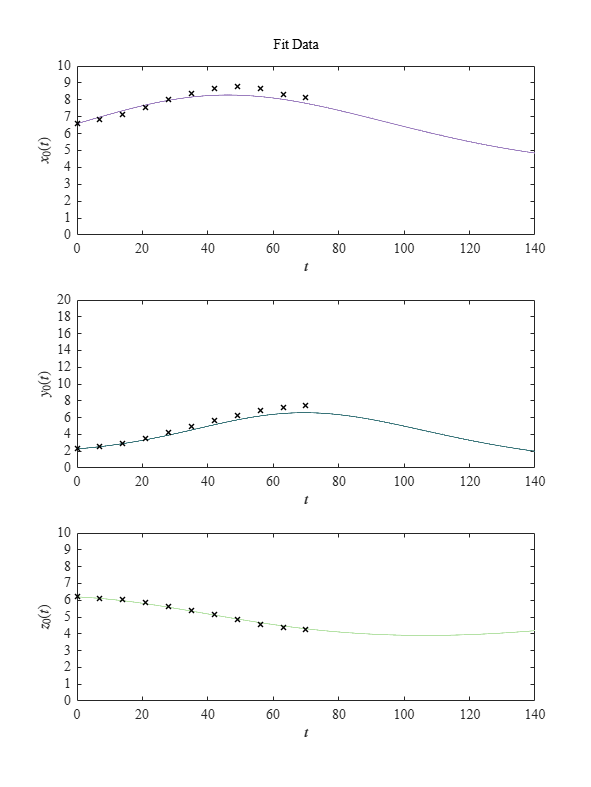

rho1 = 0.00705; rho2 = 0.0351;
rho3 = 0.00198; rho4 = 0.0667;
rho5 = 0.0187; rho6 = 0.00306;
P = [rho1, rho2, rho3, rho4, rho5, rho6];
tend = 140;
[ta, xa, ya, za] = predict(xo, yo, zo, tend, P); plotPrediction(to,xo,yo,zo,ta,xa,ya,za,140);

## t = 100 prediction

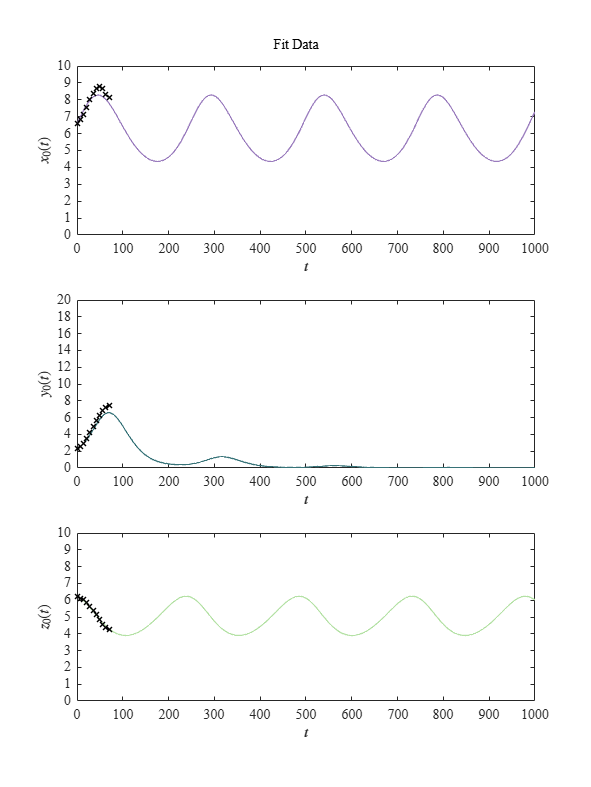

rho1 = 0.00705; rho2 = 0.0351;
rho3 = 0.00198; rho4 = 0.0667;
rho5 = 0.0187; rho6 = 0.00306;
P = [rho1, rho2, rho3, rho4, rho5, rho6];
tend = 1000;
[ta, xa, ya, za] = predict(xo, yo, zo, tend, P); plotPrediction(to,xo,yo,zo,ta,xa,ya,za,1000);

## Functions

### Plot data

function plotdata(t, x, y, z)
    set(figure(), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [1,1,15,20])
    sgtitle('Experimental Data', 'FontName', 'Times New Roman', 'FontSize', 10);
    
    colores = [155, 125, 190;
               55, 115, 120;
               180, 225, 165;
               230, 185, 235] / 255;

    % Subplot 1 - x
    subplot(3,1,1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    % plot(t, x, '-', 'LineWidth', 1, 'Color', colores(1,:)); % Línea
    plot(t, x, '.', 'MarkerSize', 10, 'LineWidth', 1, 'Color', colores(1,:));
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$x_0(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);

    % Subplot 2 - y
    subplot(3,1,2);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    % plot(t, y, '-', 'LineWidth', 1, 'Color', colores(2,:)); % Línea
    plot(t, y, '.', 'MarkerSize', 10, 'LineWidth', 1, 'Color', colores(2,:));
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$y_0(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);

    % Subplot 3 - z
    subplot(3,1,3);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    % plot(t, z, '-', 'LineWidth', 1, 'Color', colores(3,:)); % Línea
    plot(t, z, '.', 'MarkerSize', 10, 'LineWidth', 1, 'Color', colores(3,:));
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$z_0(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);
end

### Plot normalized data

function plotNormalizedData(t, x, y, z)
    set(figure(), 'Color', 'w')
    set(gcf, 'Units', 'Centimeters', 'Position', [1,1,15,20])
    sgtitle('Normalized Data', 'FontName', 'Times New Roman', 'FontSize', 10);
    
    colores = [155, 125, 190;
               55, 115, 120;
               180, 225, 165;
               230, 185, 235] / 255;

    % Subplot 1 - x
    subplot(3,1,1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    % plot(t, x, '-', 'LineWidth', 1, 'Color', colores(1,:)); % Línea
    plot(t, x, '.', 'MarkerSize', 10, 'LineWidth', 1, 'Color', colores(1,:));
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$x_0(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 1]); yticks(0:0.1:1);

    % Subplot 2 - y
    subplot(3,1,2);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    % plot(t, y, '-', 'LineWidth', 1, 'Color', colores(2,:)); % Línea
    plot(t, y, '.', 'MarkerSize', 10, 'LineWidth', 1, 'Color', colores(2,:));
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$y_0(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 1]); yticks(0:0.1:1);

    % Subplot 3 - z
    subplot(3,1,3);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    % plot(t, z, '-', 'LineWidth', 1, 'Color', colores(3,:)); % Línea
    plot(t, z, '.', 'MarkerSize', 10, 'LineWidth', 1, 'Color', colores(3,:));
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$z_0(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 1]); yticks(0:0.1:1);
end

### System regression

function [mdl, xa, ya, za] = variant(to, xo, yo ,zo, P)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    to = [to; to; to];
    fo = [xo; yo; zo];

    function fi = model(p, t)
        rho1 = p(1); rho2 = p(2);
        rho3 = p(3); rho4 = p(4); rho5 = p(5);
        rho6 = p(6);
        dt = 1E-2;
        t = reshape(t, [], 3); t = t(:,1);
        time = (0:dt:max(t))';
        n = round(max(t)/dt);
        x = zeros(length(time),1); x(1) = x0;
        y = zeros(length(time),1); y(1) = y0;
        z = zeros(length(time),1); z(1) = z0;

        for i = 1:n
            [fx, fy, fz] = f(x(i),y(i),z(i));
            xn = x(i) + fx*dt;
            yn = y(i) + fy*dt;
            zn = z(i) + fz*dt;
            [fxn, fyn, fzn] = f(xn, yn, zn);
            x(i+1) = x(i) + (fx + fxn)*dt/2;
            y(i+1) = y(i) + (fy + fyn)*dt/2;
            z(i+1) = z(i) + (fz + fzn)*dt/2;
        end

        function [dx,dy,dz] = f(x,y,z)
            dx = rho1*x*z - rho2*x;
            dy = rho3*x*y*z - rho4*y;
            % dy = rho3*y*z - rho4*y;
            % dy = rho3*x*y*z^2 - rho4*y;
            dz = rho5*z - rho6*x*z;
        end

        xi = zeros(length(t),1);  
        yi = zeros(length(t),1);
        zi = zeros(length(t),1);
        
        for i = 1:length(t)
            k = abs(time - t(i)) < 1E-9; 
            xi(i) = x(k);
            yi(i) = y(k);
            zi(i) = z(k);
        end

        fi = [xi;yi;zi];
    end

    mdl = fitnlm(to,fo,@model,P); 
    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));
    alpha = 0.05;
    CI95 = coefCI(mdl,alpha);
    dof = mdl.DFE; 
    tval = tinv(1 - alpha/2,dof);
    MoE = SE*tval;

    Parameters = ['rho1';'rho2';'rho3';'rho4';'rho5';'rho6'];
    Results = table(Parameters,Estimate,SE,MoE,CI95,pvalue);

    fprintf(['\nSample size (n): ', num2str(numel(xo))])
    fprintf(['\nParameters to be estimated (pars): ', num2str(numel(P))])
    fprintf(['\nDegrees of freedom: ', num2str(dof)])
    fprintf(['\nSignificance level (alpha): ', num2str(alpha)])
    fprintf(['\nt-Student value: ', num2str(tval)])
    fprintf(['\nR-squared: ', num2str(mdl.Rsquared.Ordinary)])
    fprintf(['\nCorrected AIC (n/pars < 40): ', num2str(mdl.ModelCriterion.AICc),'\n\n'])
    
    disp(Results)

    fa = mdl.Fitted;
    fn = reshape(fa,[],3);
    xa = fn(:,1);
    ya = fn(:,2);
    za = fn(:,3);
end

### System prediction

function [time, xa, ya, za] = predict(xo, yo ,zo, tend, P)
    x0 = xo(1); y0 = yo(1); z0 = zo(1);
    rho1 = P(1); rho2 = P(2);
    rho3 = P(3); rho4 = P(4);
    rho5 = P(5); rho6 = P(6);
    dt = 1E-2;
    time = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros(length(time),1); x(1) = x0;
    y = zeros(length(time),1); y(1) = y0;
    z = zeros(length(time),1); z(1) = z0;

    for i = 1:n
        [fx, fy, fz] = f(x(i),y(i),z(i));
        xn = x(i) + fx*dt;
        yn = y(i) + fy*dt;
        zn = z(i) + fz*dt;
        [fxn, fyn, fzn] = f(xn, yn, zn);
        x(i+1) = x(i) + (fx + fxn)*dt/2;
        y(i+1) = y(i) + (fy + fyn)*dt/2;
        z(i+1) = z(i) + (fz + fzn)*dt/2;
    end

    xa = x;
    ya = y;
    za = z;

    function [dx,dy,dz] = f(x,y,z)
        dx = rho1*x*z - rho2*x;
        dy = rho3*x*y*z - rho4*y;
        dz = rho5*z - rho6*x*z;
    end
end

### Plot results

function plotResults(to, xo, yo, zo)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,15,20]);
    sgtitle('Fit Data', 'FontName', 'Times New Roman', 'FontSize', 10);
   
    colores = [155, 125, 190;
                55, 115, 120;
                180, 225, 165;
                230, 185, 235;
                ]/255;

    % Subplot 1 - x
    subplot(3,1,1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(to, xo(:,2), '-', 'LineWidth', 1, 'Color', colores(1,:));
    plot(to, xo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$x_0(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);

    % Subplot 2 - y
    subplot(3,1,2);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(to, yo(:,2), '-', 'LineWidth', 1, 'Color', colores(2,:));
    plot(to, yo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$y_0(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);

    % Subplot 3 - z
    subplot(3,1,3);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(to, zo(:,2), '-', 'LineWidth', 1, 'Color', colores(3,:));
    plot(to, zo(:,1), 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$z_0(t)$', 'Interpreter', 'latex');
    xlim([0 70]); xticks(0:10:70);
    ylim([0 10]); yticks(0:1:10);
end


### Plot prediction

function plotPrediction(to, xo, yo, zo, ta, xa, ya, za, typeplot)
    set(figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,15,20]);
    sgtitle('Fit Data', 'FontName', 'Times New Roman', 'FontSize', 10);
   
    colores = [155, 125, 190;
               55, 115, 120;
               180, 225, 165;
               230, 185, 235]/255;

    switch typeplot
        case 140
            x_lim = [0 140];
            x_ticks = 0:20:140;
            y_lims = {[0 10], [0 20], [0 10]};
            y_ticks = {0:1:10, 0:2:20, 0:1:10};

        case 1000
            x_lim = [0 1000];
            x_ticks = 0:100:1000;
            y_lims = {[0 10], [0 20], [0 10]};
            y_ticks = {0:1:10, 0:2:20, 0:1:10};

        % Puedes añadir más casos si lo necesitas
    end

    % Subplot 1 - x
    subplot(3,1,1);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(ta, xa, '-', 'LineWidth', 1, 'Color', colores(1,:));
    plot(to, xo, 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$x_0(t)$', 'Interpreter', 'latex');
    xlim(x_lim); xticks(x_ticks);
    ylim(y_lims{1}); yticks(y_ticks{1});

    % Subplot 2 - y
    subplot(3,1,2);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(ta, ya, '-', 'LineWidth', 1, 'Color', colores(2,:));
    plot(to, yo, 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$y_0(t)$', 'Interpreter', 'latex');
    xlim(x_lim); xticks(x_ticks);
    ylim(y_lims{2}); yticks(y_ticks{2});

    % Subplot 3 - z
    subplot(3,1,3);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 10);
    hold on; box on; grid off;
    plot(ta, za, '-', 'LineWidth', 1, 'Color', colores(3,:));
    plot(to, zo, 'x', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k');
    xlabel('$t$', 'Interpreter', 'latex');
    ylabel('$z_0(t)$', 'Interpreter', 'latex');
    xlim(x_lim); xticks(x_ticks);
    ylim(y_lims{3}); yticks(y_ticks{3});
end